# Example Model- group Runtastic

We only tried to do things which were not already shown in the model provided, except the distance calculation we changed to kilometers.

First we tried to do classification of shapes by position, we tried to draw a circle and rectangles but the output by position was not at all near the actual path. Acceleration was much more reliable than position, as position sampling was unreliable by frequeency as well

## Counting the number of jumps

### 1. Preparing Data

Loading data

clear
load('sensor_data/5jumpslovro.mat'); %change it to your desired file


Zacc = Acceleration.X;
accelDatetime=Acceleration.Timestamp;


Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;
accelTime=timeElapsed(accelDatetime);


### Counting the number of jumps

First we smooth the data of the jumping, we assume that the frequency of sampling is 100Hz

Check big changes in acceleration

Characteristics of jumps: Freefall acceleration most of the time, then big acceleration upwards for a short amount

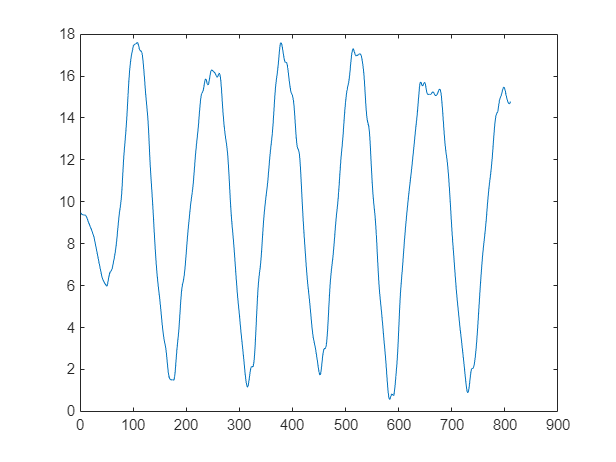


smoothaccZ = smoothdata(Zacc, "movmean", 50);
plot(smoothaccZ)

### Calculating the distance travelled

clear
load('sensor_data/circle.mat');
lon = Position.longitude;
lat = Position.latitude;
totaldis = 0;

for i = 1:(length(lat)-1)
    lat1 = lat(i);     % The first latitude
    lat2 = lat(i+1);   % The second latitude
    lon1 = lon(i);     % The first longitude
    lon2 = lon(i+1);   % The second longitude
    dis = deg2km(distance(lat1, lon1, lat2, lon2));
    totaldis = totaldis + dis;
end
stride = 0.75;                   % Average stride (m)
totaldis_m = totaldis*1000;    % Converting distance from km to m
steps = totaldis_m/stride;

disp(['The total distance traveled is: ', num2str(totaldis),' kms'])

The total distance traveled is: 0.049508 kms


disp(['You took ', num2str(steps) ' steps'])

You took 66.0106 steps


### Showing the walk using meters as standard

Linearize the distance around the point

Calculate the average point, linearize around there, so find how much latitude change is one meter and translate it

Find what change is needed for 1 km

avglon = mean(lon);
avglat = mean(lat);

h = 0.0001;

lon1 = avglon+h;
lat1 = avglat+h;

meterchangeinlon =  deg2km(distance(avglat, avglon, avglat, lon1))/h * 1000

meterchangeinlon = 5.6611e+04

meterchangeinlat = deg2km(distance(avglat, avglon, lat1, avglon))/h * 1000

meterchangeinlat = 1.1119e+05

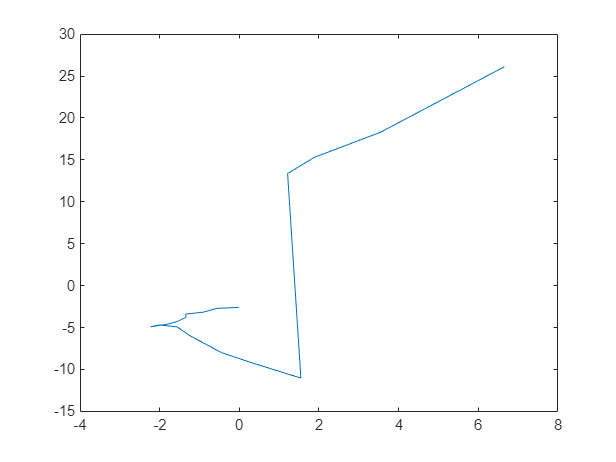


changedlat = (lat-avglat)*meterchangeinlat;
changedlon = (lon-avglon)*meterchangeinlon;

plot(changedlat, changedlon) % the path shown in meter scale

### Classification of jumps

Count the number of jumps

Check big changes in acceleration

Characteristics of jumps: Freefall acceleration most of the time, then big acceleration upwards for a short amount

## Classifying laps/intervals

Observe rapid changes in x and y accelerations to count the number of intervals